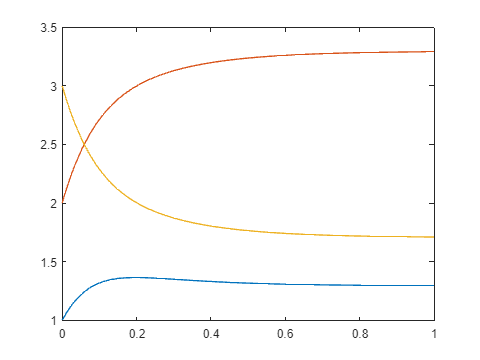

format long
%%%Parte1
%Script para resolver la ED del Reactor Quimico
a=5; b=2; u1=3; u2=5;
f=@(t,x)[a*(u1-x(1))-b*x(1).*x(2); a*(u2-x(2))-b*x(1).*x(2); -a*x(3)+b*x(1).*x(2)];

t0=0; tf=1; tspan=[t0 tf]; x0=[1 2 3];
[t,x]=ode45(f,tspan,x0);
plot(t,x)


prev = x;

%%%%%Parte 2
%%%completar

syms x(t) y(t)

sol = dsolve(diff(x,t) == y,   diff(y,t) == -x -0.125*y,   x(0)==1,y(0)==0);
x1fun = matlabFunction(sol.x);
x2fun = matlabFunction(sol.y);

x1=x1fun(1)

x1 =    0.558551602703109


x2=x2fun(1)

x2 =   -0.791041527894495



x = prev;

x

x =    1.000000000000000   2.000000000000000   3.000000000000000
   1.047636673619555   2.088637274605914   2.911362725394086
   1.090313210798231   2.170633338381470   2.829366661618530
   1.128393160511338   2.246420621077446   2.753579378922554
   1.162240856540473   2.316429635575294   2.683570364424706
   1.226686173091466   2.459235123811645   2.540764876188355
   1.274212327789793   2.577860572404225   2.422139427595775
   1.308056772602032   2.676212601055920   2.323787398944080
   1.331520016269339   2.758207487774972   2.241792512225028
   1.347293985552453   2.826500109539382   2.173499890460618
